% Clear workspace and command window
clear; clc; close all;

%% 1. Initialize and Load the Network
% Replace with your specific EPANET input file path
inp_file = 'Net1.inp'; 

% Open the EPANET toolkit object
d = epanet(inp_file);

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.



%% 2. Configure Water Quality Settings
% Set the quality analysis type: 
% 'CHEM' = Chemical, 'AGE' = Water Age, 'TRACE' = Source Tracing
d.setQualityType('CHEM', 'mg/L'); 

% Example: Set an initial chemical concentration (e.g., Chlorine) at a specific node
% Let's assume Node Index 1 is an injection point or reservoir
target_node_index = 1; 
initial_concentration = 1.0; % 1.0 mg/L
d.setNodeInitialQuality(target_node_index, initial_concentration);

%% 3. Run Extended Period Water Quality Simulation (FIXED LOOP)
% Retrieve simulation time parameters (returned in seconds)
duration = d.getTimeSimulationDuration;
hyd_step = d.getTimeHydraulicStep;

% Initialize tracking variables
time_steps = [];
node_quality_history = [];
current_time = 0;
step_index = 1;

% Loop through the extended period simulation timeline
while current_time <= duration
    % Solve hydraulics for the current time period
    d.solveCompleteHydraulics;
    
    % Track current simulation time converted to hours
    time_steps(step_index) = current_time / 3600; 
    
    % Store actual quality concentrations for all nodes at this time step
    node_quality_history(:, step_index) = d.getNodeActualQuality; 
    
    % Increment time step counter manually based on your file's step size
    current_time = current_time + hyd_step;
    step_index = step_index + 1;
end

disp('Water quality simulation loop complete.');

Water quality simulation loop complete.


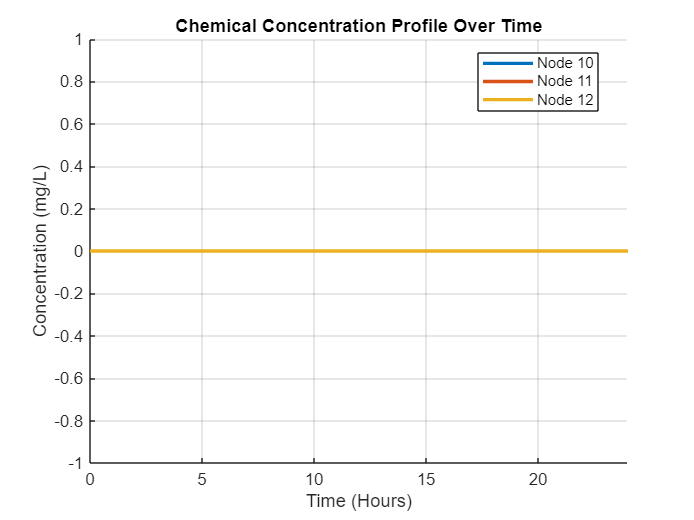


%% 4. Plot Water Quality Tracking Results
figure('Name', 'Water Quality Tracking Over Time', 'NumberTitle', 'off');
hold on;
grid on;

% Select specific node indices you want to analyze (e.g., nodes 1, 2, and 3)
% Modify these numbers based on how many nodes are in your Net1.inp file
nodes_to_plot = [1, 2, 3]; 
node_ids = d.getNodeNameID;

for idx = nodes_to_plot
    % Plot concentration history for selected nodes
    plot(time_steps, node_quality_history(idx, :), 'LineWidth', 2, ...
         'DisplayName', ['Node ' node_ids{idx}]);
end

% Formatting the plot
title('Chemical Concentration Profile Over Time');
xlabel('Time (Hours)');
ylabel('Concentration (mg/L)');
xlim([0, duration/3600]);
legend('Location', 'best');
hold off;


%% 5. Unload Toolkit
d.unload;

EPANET Class is unloaded


disp('All processes finished successfully.');

All processes finished successfully.
